# Kelly Cosine Approximation

First, plot to compare between cosine and kelly cosine approximation

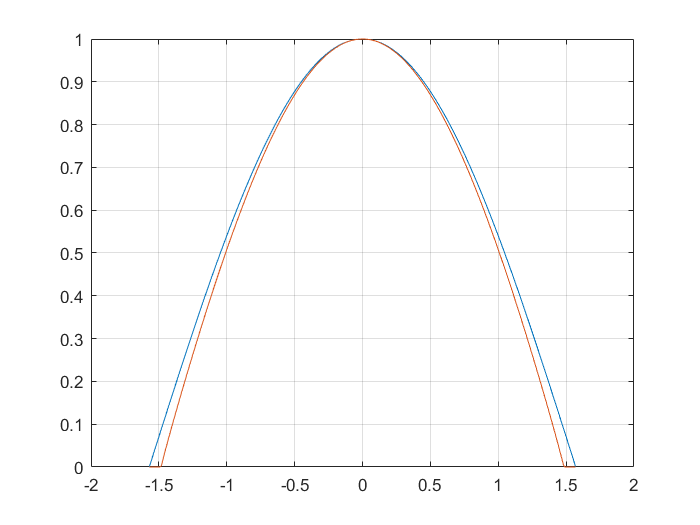

theta=-pi/2:0.01:pi/2;
y=cos(theta);

%Kelly cosine
kcos=zeros(1,length(theta));
for i=1:length(theta)
    th_s=abs(theta(i));
    if th_s<=pi/2
        kcos(i)=0;
    end
    if th_s<17*pi/36
        kcos(i)=(cos(1.059*th_s))^0.949;
    end

end

%plot
figure()
plot(theta,y)
hold on
plot(theta,kcos)
grid on